format shortg
clear all

# Oppgave 1

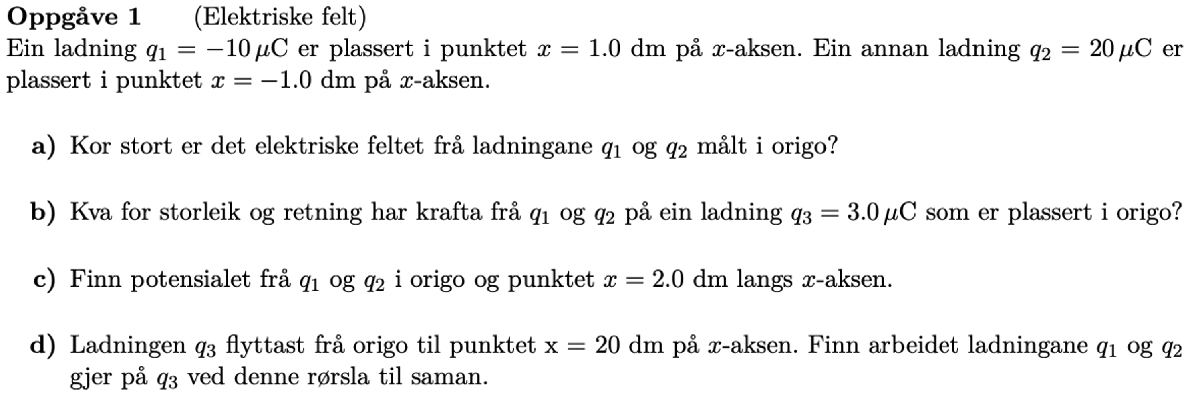

q1 = -10 * 10^-6; % C
x1 = 1.0 * 10^-1; % m
q2 =  20 * 10^-6; % C
x2 = -1.0* 10^-1; % m

a)

E_1 = ElektriskFeltstyrkeFraPunktladning(0, q1, x1);
E_2 = ElektriskFeltstyrkeFraPunktladning(0, q2, x2);
E = E_1 + E_2

E =    2.6963e+07


b)

q3 = 3.0 * 10^-6; % C
F = q3 * E

F =        80.888


retningen blir da mot positiv x, altså i samme retning som feltet.

c)

I Origo:

U_origo = PotensialFraPunktladning(0, q1, x1) + PotensialFraPunktladning(0, q2, x2);
signif(U_origo, 2)

ans =       900000


2dm på x-aksen:

x = 2.0 * 10^-1; % m
U_2dm = PotensialFraPunktladning(0, q1, x-x1) + PotensialFraPunktladning(0, q2, x-x2);
signif(U_2dm, 2)

ans =      -300000


d)

Finner potensiell energi i origo:

PotensiellEnergi_origo = U_origo * q3

PotensiellEnergi_origo =        2.6963


PotensiellEnergi_2dm = U_2dm * q3

PotensiellEnergi_2dm =      -0.89876


Arbeidet er da forskjellen i denne energien:

W = -(PotensiellEnergi_2dm - PotensiellEnergi_origo);
signif(W, 3) % Joule

ans =           3.6
